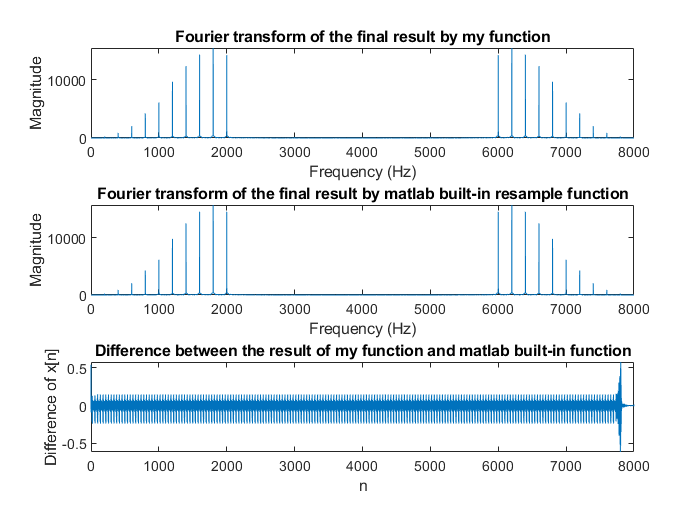

clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

signal_supersition = sum(x, 1);
% subplot(2,1,1);
% stem(n, signal_supersition);
% stem(n*T, signal_supersition);
% xlabel('n');
% ylabel('x(n)');
% title('Signal sampled at 5kHz in time domain');
% soundsc(signal_supersition);

fft_for_signal = fft(signal_supersition);
f = 0:4999;
% subplot(2,1,2);
% plot(f, abs(fft_for_signal));
% xlabel('frequency (Hz)');
% ylabel('Magnitude of the transform');
% title('Signal sampled at 5kHz in frequency domain');
% hold off;
% Read the audio file into workspace.
[samples_of_the_filter, fs_of_filter] = audioread('telephoneIR.wav');



% figure
% k = 0:21999;
% plot(k, resampled_signal_by_matlab)
% fft_for_resampled_signal = fft(resampled_signal_by_matlab);
% plot(k, abs(fft_for_resampled_signal))

% First in order to do convolution operation to original signal and filter,
% we have to make their sampling frequency identical, thus resampling the
% original signal to 22kHz, which is the sampling frequency of the filter.
signal_after_resample_22kHz = resample_by_factor_p_over_q(signal_supersition, 22, 5);
% Convolve the resampled signal with the filter in time domain.
signal_after_being_filtered_22kHz = conv(signal_after_resample_22kHz, samples_of_the_filter','same');
fft_for_filter_signal_22kHz = fft(signal_after_being_filtered_22kHz);
% figure
k = 0:21999;
filtered_signal_resample_to_8kHz = resample_by_factor_p_over_q(signal_after_being_filtered_22kHz, 8, 22);
% soundsc(filtered_signal_resample_to_8kHz);
subplot(3,1,1);
fft_final_by_me = fft(filtered_signal_resample_to_8kHz);
k = 0:7999;
plot(k, abs(fft_final_by_me));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title(['Fourier transform of the final result by my function']);
hold on;
% ----------------------------------------------------By matlab here.
resampled_signal_by_matlab = resample(signal_supersition, 22, 5);
signal_after_filter_by_matlab = conv(resampled_signal_by_matlab, samples_of_the_filter, 'same');
final_8kHz_filtered_signal = resample(signal_after_filter_by_matlab, 8, 22);
k = 0:7999;
subplot(3,1,2);
fft_for_resampled_signal = fft(final_8kHz_filtered_signal);
plot(k, abs(fft_for_resampled_signal));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title(['Fourier transform of the final result by matlab built-in resample function']);
hold on;
% ------------------------------------------------------

subplot(3,1,3);
plot(k, filtered_signal_resample_to_8kHz - final_8kHz_filtered_signal);
xlabel('n');
ylabel('Difference of x[n]');
title('Difference between the result of my function and matlab built-in function');

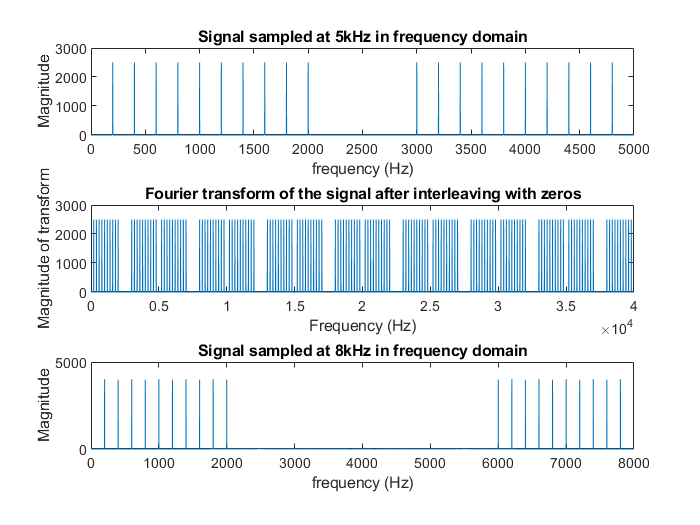

clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

signal_supersition = sum(x, 1);

fft_for_signal = fft(signal_supersition);
f = 0:4999;
subplot(3,1,1);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude');
title('Signal sampled at 5kHz in frequency domain');
ylim([0 3000]);

final_signal = Resample_5kHz_to_8kHz(signal_supersition);
fft_final = fft(final_signal);
f = 0:7999;
subplot(3,1,3);
plot(f, abs(fft_final));
xlabel('frequency (Hz)');
ylabel('Magnitude');
title('Signal sampled at 8kHz in frequency domain');
ylim([0 5000]);

function output_signal = Resample_5kHz_to_8kHz(input_signal)
% Output:
%       output_signal: The signal after being resampled.
% Input:
%       input_signal: Data for the input signal.   
% This function will resample the required signal of 5kHz with duration 1
% second to 8kHz with duration 1 second.
% The anti-aliasing operation is done with a rectangular window, which
% corresponds to a sinc function in time domain, I chose the length of the
% sinc function to be 601.
% Author: Yuchen MU
% Last modified date: 15/10/19

% ----------------------------------------------------------------
% Up-sampling part.
signal_interleave_with_zeros = zeros(1, 40000);
% Add 7 zeros between two samples.
index = 1;
for i = 1:40000
    if mod(i, 8) == 1
        signal_interleave_with_zeros(i) = input_signal(index);
        index = index + 1;
    end
end
fft_for_signal_interleave_with_zeros = fft(signal_interleave_with_zeros);
f = 0:39999;
% figure
subplot(3,1,2);
plot(f, abs(fft_for_signal_interleave_with_zeros));
xlabel('Frequency (Hz)');
ylabel('Magnitude of transform');
title('Fourier transform of the signal after interleaving with zeros');
ylim([0 3000]);
% hold off;

% ----------------------------------------------------------------
% Anti-aliasing part.
% Filter out any frequency components higher than 2.5kHz (half of the
% original sampling frequency ), by applying a rectangular window, which
% corresponds to a sinc function in time domain.
% length of the sinc function is 601 points.
t = -300*(1/40000):(1/40000):300*(1/40000);
filter_sinc = sinc(5000*t);
signal_after_filtering = conv(signal_interleave_with_zeros, filter_sinc, 'same');
% Plot the signal in frequency domain after being filtered.
% figure
% k = 0:39999;
% fft_after_conv = fft(signal_after_filtering);
% plot(k, abs(fft_after_conv));
% xlabel('Frequency (Hz)');
% ylabel('Magnitude');
% title('Fourier transform of the signal after being filtered');


% ----------------------------------------------------------------
% Down-sampling part.
% Decimation operation.
signal_after_downsampling = zeros(1, 8000);
index = 1;
% Take one sample out of each 5 samples.
for i = 1:40000
    if mod(i, 5) == 1
        signal_after_downsampling(index) = signal_after_filtering(i);
        index = index + 1;
    end
end
% Plot the signal after being resampled in time domain.
% k = 0:7999;
% figure
% subplot(2,1,1);
% stem(k, signal_after_downsampling);
% xlabel('n');
% ylabel('x(n)');
% title('Signal sampled at 8kHz in time domain');
% % Plot the signal after being resampled in frequency domain.
% fft_for_signal_after_downsampling = fft(signal_after_downsampling);
% subplot(2,1,2);
% plot(k, abs(fft_for_signal_after_downsampling));
% xlabel('Frequency (Hz)');
% ylabel('Magnitude of the transform');
% title('Fourier transform of the signal sampled at 8kHz');
% ylim([0 4500]);
% soundsc(signal_after_downsampling);
output_signal = signal_after_downsampling;
end

% function [output_signal] = resample_by_factor_p_over_q(input_signal, p, q)
% % Output:
% %       output_signal: The signal after being resampled.
% % Input:
% %       input_signal: Data for the input signal.
% %       p: The sampling frequency that we want to resample to, in kHz.
% %       q: The sampling frequency for the input signal, in kHz.
% % This function will resample the signal of qkHz with duration 1 second to
% % pkHz with duration 1 second.
% % The anti-aliasing operation is done with a rectangular window, which
% % corresponds to a sinc function in time domain, I also truncated sinc
% % function based on different resampling needs.
% % Author: Yuchen MU
% % Last modified date: 15/10/19
% 
% % ----------------------------------------------------------------
% % Up-sampling part
% % Interleave the signal with zeros.
% signal_interleave_with_zeros = zeros(1, q*1000*p);
% index = 1;
% for i = 1:q*1000*p
%     if mod(i, p) == 1
%         signal_interleave_with_zeros(i) = input_signal(index);
%         index = index + 1;
%     end
% end
% % Plot the signal in frequency domain after interleaving zeros.
% fft_for_signal_interleave_with_zeros = fft(signal_interleave_with_zeros);
% f = 0:(q*1000*p)-1;
% % figure
% subplot(3,1,2);
% plot(f, abs(fft_for_signal_interleave_with_zeros));
% xlabel('Frequency (Hz)');
% ylabel('Magnitude');
% title('Fourier transform of the signal after interleaving with zeros');
% xlim([0 q*1000*p]);
% ylim([0 3000]);
% % hold off;
% 
% % ----------------------------------------------------------------
% % Anti-aliasing part
% % There are p copies of the original signal in the frequency domain, we
% % have to filter out the frequency components higher than half of the
% % original sampling frequency, i.e., ((q*1000)/2)Hz.
% 
% % Filtering operation, assuming rectangular window is used.
% % adapative length of the sinc function, based on different needs.
% N_for_sinc = (p*q*1000)/50;
% t = -(N_for_sinc/2)*(1/(p*q*1000)):(1/(p*q*1000)):(N_for_sinc/2)*(1/(p*q*1000));
% % Filter out frequency component higher than half of the original sampling
% % frequency, i.e., ((q*1000)/2)Hz.
% filter_sinc = sinc(q*1000*t);
% % Convolve in time domain.
% signal_after_filtering = conv(signal_interleave_with_zeros, filter_sinc, 'same');
% 
% % Plot the signal in frequency domain after being filtered.
% % figure
% k = 0:(q*p*1000)-1;
% % fft_after_conv = fft(signal_after_filtering);
% % plot(k, abs(fft_after_conv));
% % xlabel('Frequency (Hz)');
% % ylabel('Magnitude');
% % title('Fourier transform of the signal after being filtered');
% % xlim([0 p*q*1000]);
% 
% % ----------------------------------------------------------------
% % Down-sampling part
% % Decimation operation
% signal_after_downsampling = zeros(1, p*1000);
% index = 1;
% for i = 1:q*1000*p
%     if mod(i, q) == 1
%         signal_after_downsampling(index) = signal_after_filtering(i);
%         index = index + 1;
%     end
% end
% % Plot the downsampled signal in time domain.
% % k = 0:(1000*p)-1;
% % figure
% % subplot(2,1,1);
% % stem(k, signal_after_downsampling);
% % xlabel('n');
% % ylabel('x(n)');
% % title(['Signal sampled at ' , int2str(p), 'kHz in time domain']);
% % xlim([0 p*(10^3)]);
% % Plot the downsampled signal in frequency domain.
% % fft_for_signal_after_downsampling_ = fft(signal_after_downsampling);
% % subplot(2,1,2);
% % plot(k, abs(fft_for_signal_after_downsampling_));
% % xlabel('Frequency (Hz)');
% % ylabel('Magnitude of the transform');
% % title(['Fourier transform of the signal sampled at ', int2str(p), 'kHz']);
% % xlim([0 p*(10^3)]);
% % soundsc(signal_after_downsampling);
% output_signal = signal_after_downsampling;
% end
% 


